### Megoldás közelítése

A 3 dimenziós FEM-hez tartozó együttható mátrix:

% belso pontok szama
N =4;

% lepeshossz
h = 1/(N+1)

h = 0.2000


e = ones(N,1);

D = 8/3*speye(N);
B = spdiags([-1/6*e,-1/6*e],[-1,1],N,N);
C = spdiags([-1/12*e,-1/6*e,-1/12*e],[-1,0,1],N,N);

Tmp1 = spdiags([e,e],[-1,1],N,N);
S = kron(speye(N),D) + kron(Tmp1,B);
R = kron(speye(N),B) + kron(Tmp1,C);

A_h = h * (kron(speye(N),S) + kron(Tmp1,R));
8*h/3

ans = 0.5333

-h/6

ans = -0.0333

-h/12

ans = -0.0167


A_h(1,:)

ans =    (1,1)       0.5333
   (1,6)      -0.0333
   (1,18)     -0.0333
   (1,21)     -0.0333
   (1,22)     -0.0167


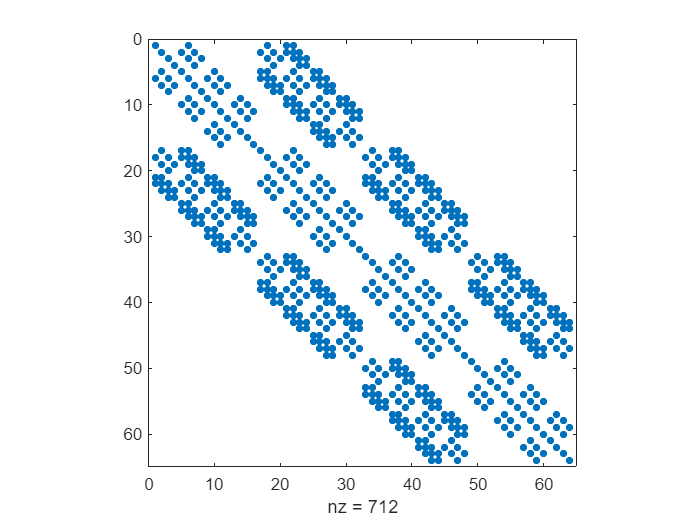

spy(A_h);

Numerikusan közelített értékek a rácspontokban

% 3d
[xi,yj,zk] = meshgrid(h:h:1-h,h:h:1-h,h:h:1-h);
tmp=sin(pi*xi).*sin(pi*yj).*sin(pi*zk)

tmp = tmp(:,:,1) =

    0.2031    0.3286    0.3286    0.2031
    0.3286    0.5317    0.5317    0.3286
    0.3286    0.5317    0.5317    0.3286
    0.2031    0.3286    0.3286    0.2031


tmp(:,:,2) =

    0.3286    0.5317    0.5317    0.3286
    0.5317    0.8602    0.8602    0.5317
    0.5317    0.8602    0.8602    0.5317
    0.3286    0.5317    0.5317    0.3286


tmp(:,:,3) =

    0.3286    0.5317    0.5317    0.3286
    0.5317    0.8602    0.8602    0.5317
    0.5317    0.8602    0.8602    0.5317
    0.3286    0.5317    0.5317    0.3286


tmp(:,:,4) =

    0.2031    0.3286    0.3286    0.2031
    0.3286    0.5317    0.5317    0.3286
    0.3286    0.5317    0.5317    0.3286
    0.2031    0.3286    0.3286    0.2031


exact=reshape(pagetranspose(tmp),N^3,1);
f=3*pi^2*reshape(pagetranspose(tmp),N^3,1);
rhs = f*h^3;
% numerikusan kozelitett ertekek
y = A_h\rhs;

ybrick=reshape(y,N,N,N);
ybrick = pagetranspose(ybrick)

ybrick = ybrick(:,:,1) =

    0.2394    0.3874    0.3874    0.2394
    0.3874    0.6268    0.6268    0.3874
    0.3874    0.6268    0.6268    0.3874
    0.2394    0.3874    0.3874    0.2394


ybrick(:,:,2) =

    0.3874    0.6268    0.6268    0.3874
    0.6268    1.0141    1.0141    0.6268
    0.6268    1.0141    1.0141    0.6268
    0.3874    0.6268    0.6268    0.3874


ybrick(:,:,3) =

    0.3874    0.6268    0.6268    0.3874
    0.6268    1.0141    1.0141    0.6268
    0.6268    1.0141    1.0141    0.6268
    0.3874    0.6268    0.6268    0.3874


ybrick(:,:,4) =

    0.2394    0.3874    0.3874    0.2394
    0.3874    0.6268    0.6268    0.3874
    0.3874    0.6268    0.6268    0.3874
    0.2394    0.3874    0.3874    0.2394


A közelítés hibája:

% a kozelitett ertekek elterese a pontos ertekektol max normaban
diff = exact-y;

norm(diff,'inf')

ans = 0.1539

%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%

pontosított jobboldal

[p1,r1,s1] = meshgrid(h/2:h:1-3*h/2,h/2:h:1-3*h/2,h/2:h:1-3*h/2);
[p2,r2,s2] = meshgrid(3*h/2:h:1-h/2,h/2:h:1-3*h/2,h/2:h:1-3*h/2);
[p3,r3,s3] = meshgrid(h/2:h:1-3*h/2,h/2:h:1-3*h/2,3*h/2:h:1-h/2);
[p4,r4,s4] = meshgrid(3*h/2:h:1-h/2,h/2:h:1-3*h/2,3*h/2:h:1-h/2);

[p5,r5,s5] = meshgrid(h/2:h:1-3*h/2,3*h/2:h:1-h/2,h/2:h:1-3*h/2);
[p6,r6,s6] = meshgrid(3*h/2:h:1-h/2,3*h/2:h:1-h/2,h/2:h:1-3*h/2);
[p7,r7,s7] = meshgrid(h/2:h:1-3*h/2,3*h/2:h:1-h/2,3*h/2:h:1-h/2);
[p8,r8,s8] = meshgrid(3*h/2:h:1-h/2,3*h/2:h:1-h/2,3*h/2:h:1-h/2);


sum_fqi = sin(pi*p1).*sin(pi*r1).*sin(pi*s1)+sin(pi*p2).*sin(pi*r2).*sin(pi*s2)+sin(pi*p3).*sin(pi*r3).*sin(pi*s3)+sin(pi*p4).*sin(pi*r4).*sin(pi*s4)+sin(pi*p5).*sin(pi*r5).*sin(pi*s5)+sin(pi*p6).*sin(pi*r6).*sin(pi*s6)+sin(pi*p7).*sin(pi*r7).*sin(pi*s7)+sin(pi*p8).*sin(pi*r8).*sin(pi*s8);
f_javitott=3*pi^2*reshape(pagetranspose(sum_fqi),N^3,1);
rhs_javitott = f*h^3;
y_javitott = A_h\rhs_javitott;
diff_javitott = exact-y_javitott;

norm(diff,'inf')

ans = 0.1539

norm(diff_javitott,'inf')

ans = 0.1539

## hiba:

pontos_normanegyzet = 3*pi^2/8;


numerikus_normanegyzet = dot(A_h*y, y)

numerikus_normanegyzet = 4.3631

pontos_normanegyzet-numerikus_normanegyzet

ans = -0.6620

hiba_negyzet_absz = abs(pontos_normanegyzet-numerikus_normanegyzet)

hiba_negyzet_absz = 0.6620

Hiba:

sqrt(hiba_negyzet_absz)

ans = 0.8137

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%% 2. feladat %%%

## c kiszámolás 3D-ben

ertek_bal_oldal= hiba_negyzet_absz

ertek_bal_oldal = 0.6620

%%%%%%%%%%%%%%%%%%%%%%%%

[X,Y,Z]=meshgrid(0:h:1,0:h:1,0:h:1);

y_extended = zeros(N+2,N+2,N+2);
y_extended(2:N+1,2:N+1,2:N+1) = ybrick;

%minden kis kockában eltárolunk egy együtthatómátrixot, amivel majd ki
%tudjuk számolni a közelítő értékekre illesztett görbe paramétereit

coeffs = ones(8, 8, N+1, N+1, N+1);

% 2. oszlop
coeffs(1,2, :, :,:) = X(1:N+1,1:N+1,1:N+1);
coeffs(3,2, :, :,:) = X(1:N+1,1:N+1,1:N+1);
coeffs(5,2, :, :,:) = X(1:N+1,1:N+1,1:N+1);
coeffs(7,2, :, :,:) = X(1:N+1,1:N+1,1:N+1);

coeffs(2,2, :, :,:) = X(2:N+2,2:N+2,2:N+2);
coeffs(4,2, :, :,:) = X(2:N+2,2:N+2,2:N+2);
coeffs(6,2, :, :,:) = X(2:N+2,2:N+2,2:N+2);
coeffs(8,2, :, :,:) = X(2:N+2,2:N+2,2:N+2);

% 3. oszlop
coeffs(1,3, :, :,:) = Y(1:N+1,1:N+1,1:N+1);
coeffs(2,3, :, :,:) = Y(1:N+1,1:N+1,1:N+1);
coeffs(5,3, :, :,:) = Y(1:N+1,1:N+1,1:N+1);
coeffs(6,3, :, :,:) = Y(1:N+1,1:N+1,1:N+1);

coeffs(3,3, :, :,:) = Y(2:N+2,2:N+2,2:N+2);
coeffs(4,3, :, :,:) = Y(2:N+2,2:N+2,2:N+2);
coeffs(7,3, :, :,:) = Y(2:N+2,2:N+2,2:N+2);
coeffs(8,3, :, :,:) = Y(2:N+2,2:N+2,2:N+2);

% 4. oszlop
coeffs(1,4, :, :,:) = Z(1:N+1,1:N+1,1:N+1);
coeffs(2,4, :, :,:) = Z(1:N+1,1:N+1,1:N+1);
coeffs(3,4, :, :,:) = Z(1:N+1,1:N+1,1:N+1);
coeffs(4,4, :, :,:) = Z(1:N+1,1:N+1,1:N+1);

coeffs(5,4, :, :,:) = Z(2:N+2,2:N+2,2:N+2);
coeffs(6,4, :, :,:) = Z(2:N+2,2:N+2,2:N+2);
coeffs(7,4, :, :,:) = Z(2:N+2,2:N+2,2:N+2);
coeffs(8,4, :, :,:) = Z(2:N+2,2:N+2,2:N+2);

% 5. oszlop
coeffs(1,5, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(1:N+1,1:N+1,1:N+1);
coeffs(5,5, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(1:N+1,1:N+1,1:N+1);

coeffs(2,5, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(1:N+1,1:N+1,1:N+1);
coeffs(6,5, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(1:N+1,1:N+1,1:N+1);

coeffs(3,5, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(2:N+2,2:N+2,2:N+2);
coeffs(7,5, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(2:N+2,2:N+2,2:N+2);

coeffs(4,5, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(2:N+2,2:N+2,2:N+2);
coeffs(8,5, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(2:N+2,2:N+2,2:N+2);

% 6. oszlop
coeffs(1,6, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);
coeffs(3,6, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);

coeffs(2,6, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);
coeffs(4,6, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);

coeffs(5,6, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);
coeffs(7,6, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);

coeffs(6,6, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);
coeffs(8,6, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);

% 7. oszlop
coeffs(1,7, :, :,:) = Y(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);
coeffs(2,7, :, :,:) = Y(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);

coeffs(3,7, :, :,:) = Y(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);
coeffs(4,7, :, :,:) = Y(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);

coeffs(5,7, :, :,:) = Y(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);
coeffs(6,7, :, :,:) = Y(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);

coeffs(7,7, :, :,:) = Y(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);
coeffs(8,7, :, :,:) = Y(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);

% 8. oszlop
coeffs(1,8, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);
coeffs(2,8, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(1:N+1,1:N+1,1:N+1).*Z(1:N+1,1:N+1,1:N+1);
coeffs(3,8, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);
coeffs(4,8, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(2:N+2,2:N+2,2:N+2).*Z(1:N+1,1:N+1,1:N+1);

coeffs(5,8, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);
coeffs(6,8, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(1:N+1,1:N+1,1:N+1).*Z(2:N+2,2:N+2,2:N+2);
coeffs(7,8, :, :,:) = X(1:N+1,1:N+1,1:N+1).*Y(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);
coeffs(8,8, :, :,:) = X(2:N+2,2:N+2,2:N+2).*Y(2:N+2,2:N+2,2:N+2).*Z(2:N+2,2:N+2,2:N+2);


% minden négyzethez tartozik jobb oldal is
rhs_vals = zeros(8,1,N+1,N+1,N+1);


rhs_vals(1,1,:,:,:) = y_extended(1:N+1,1:N+1,1:N+1);
rhs_vals(2,1,:,:,:) = y_extended(1:N+1,2:N+2,1:N+1);
rhs_vals(3,1,:,:,:) = y_extended(2:N+2,1:N+1,1:N+1);
rhs_vals(4,1,:,:,:) = y_extended(2:N+2,2:N+2,1:N+1);

rhs_vals(5,1,:,:,:) = y_extended(1:N+1,1:N+1,2:N+2);
rhs_vals(6,1,:,:,:) = y_extended(1:N+1,2:N+2,2:N+2);
rhs_vals(7,1,:,:,:) = y_extended(2:N+2,1:N+1,2:N+2);
rhs_vals(8,1,:,:,:) = y_extended(2:N+2,2:N+2,2:N+2);



% minden kockán Gauss-eliminációval megoldjuk az egyenletrendszert, így
% megkapjuk a görbe paramétereit

params = ones(8,N+1,N+1,N+1);
for i = 1:N+1
    for j = 1:N+1
        for k = 1:N+1
            %params(:,1,i,j,k) = coeffs(:,:,i,j,k)\rhs_vals(:,1,i,j,k);
            
            params(:,j,i,k) = coeffs(:,:,j,i,k)\rhs_vals(:,1,j,i,k);
        end
    end
end
params;


a_T = zeros(N+1,N+1,N+1);
a_T(:,:,:) = params(1,:,:,:);
b_T = zeros(N+1,N+1,N+1);
b_T(:,:,:) = params(2,:,:,:);
c_T = zeros(N+1,N+1,N+1);
c_T(:,:,:) = params(3,:,:,:);
d_T = zeros(N+1,N+1,N+1);
d_T(:,:,:) = params(4,:,:,:);

e_T = zeros(N+1,N+1,N+1);
e_T(:,:,:) = params(5,:,:,:);
f_T = zeros(N+1,N+1,N+1);
f_T(:,:,:) = params(6,:,:,:);
g_T = zeros(N+1,N+1,N+1);
g_T(:,:,:) = params(7,:,:,:);
h_T = zeros(N+1,N+1,N+1);
h_T(:,:,:) = params(8,:,:,:);

## Négyzetek 1.

y_hatul = Y(1:N+1,2:N+1,1:N+1);
y_elol = Y(2:N+2,2:N+1,1:N+1);

z_lent = Z(1:N+1,2:N+1,1:N+1);
z_fent = Z(1:N+1,2:N+1,2:N+2);

size(y_hatul)

ans =      5     4     5


b2 = b_T(:,2:N+1,:);
b1 = b_T(:,1:N,:);

e2 = e_T(:,2:N+1,:);
e1 = e_T(:,1:N,:);

f2 = f_T(:,2:N+1,:);
f1 = f_T(:,1:N,:);

h2 = h_T(:,2:N+1,:);
h1 = h_T(:,1:N,:);

% az ugrós érték kiszámolva minden 1. típusú négyzeten
 ertek_1_negyzeteken = zeros(N,N+1,N+1);

% segédváltozók
p1 = b1.^2+b2.^2-2.*b1.*b2;
p2 = 2*b1.*e1+2.*b2.*e2-2.*b1.*e2-2.*b2.*e1;
p3 = 2*b1.*f1+2.*b2.*f2-2.*b1.*f2-2.*b2.*f1;
p4 = 2*b2.*h2+2*e2.*f2+2*b1.*h1+2*e1.*f1-2*e2.*f1-2*f2.*e1-2*b2.*h1-2*h2.*b1;
p5 = e1.^2+e2.^2-2.*e1.*e2;
p6 = f1.^2+f2.^2-2.*f1.*f2;
p7 = 2*e1.*h1+2.*e2.*h2-2.*e2.*h1-2.*h2.*e1;
p8 = 2*f1.*h1+2.*f2.*h2-2.*f2.*h1-2.*h2.*f1;
p9 = h1.^2+h2.^2-2.*h1.*h2;

q1 = p1.*y_elol-p1.*y_hatul+1/2*p2.*y_elol.^2-1/2*p2.*y_hatul.^2+1/3*p5.*y_elol.^3- 1/3*p5.*y_hatul.^3;
q2 = p3.*y_elol-p3.*y_hatul+1/2*p4.*y_elol.^2-1/2*p4.*y_hatul.^2+1/3*p7.*y_elol.^3- 1/3*p7.*y_hatul.^3;
q3 = p6.*y_elol-p6.*y_hatul+1/2*p8.*y_elol.^2-1/2*p8.*y_hatul.^2+1/3*p9.*y_elol.^3- 1/3*p9.*y_hatul.^3;

ertek_1_negyzeteken = q1.*z_fent-q1.*z_lent+1/2*q2.*z_fent.^2-1/2*q2.*z_lent.^2+1/3*q3.*z_fent.^3-1/3*q3.*z_lent.^3;


## Négyzetek 2.

x_bal  = X(2:N+1,1:N+1,1:N+1);
x_jobb = X(2:N+1,2:N+2,1:N+1);

z_lent = Z(2:N+1,1:N+1,1:N+1);
z_fent = Z(2:N+1,1:N+1,2:N+2);

size(x_bal)

ans =      4     5     5


c2 = c_T(2:N+1,:,:);
c1 = c_T(1:N,:,:);

e2 = e_T(2:N+1,:,:);
e1 = e_T(1:N,:,:);

g2 = g_T(2:N+1,:,:);
g1 = g_T(1:N,:,:);

h2 = h_T(2:N+1,:,:);
h1 = h_T(1:N,:,:);

% segédváltozók

p1 = c1.^2+c2.^2-2.*c1.*c2;
p2 = 2*c1.*e1+2.*c2.*e2-2.*c1.*e2-2.*c2.*e1;
p3 = 2*c1.*g1+2.*c2.*g2-2.*c1.*g2-2.*c2.*g1;
p4 = 2*c2.*h2+2*e2.*g2+2*c1.*h1+2*e1.*g1-2*e2.*g1-2*g2.*e1-2*c2.*h1-2*h2.*c1;
p5 = e1.^2+e2.^2-2.*e1.*e2;
p6 = g1.^2+g2.^2-2.*g1.*g2;
p7 = 2*e1.*h1+2.*e2.*h2-2.*e2.*h1-2.*h2.*e1;
p8 = 2*g1.*h1+2.*g2.*h2-2.*g2.*h1-2.*h2.*g1;
p9 = h1.^2+h2.^2-2.*h1.*h2;


q1 = p1.*x_jobb-p1.*x_bal+1/2*p2.*x_jobb.^2-1/2*p2.*x_bal.^2+1/3*p5.*x_jobb.^3- 1/3*p5.*x_bal.^3;
q2 = p3.*x_jobb-p3.*x_bal+1/2*p4.*x_jobb.^2-1/2*p4.*x_bal.^2+1/3*p7.*x_jobb.^3- 1/3*p7.*x_bal.^3;
q3 = p6.*x_jobb-p6.*x_bal+1/2*p8.*x_jobb.^2-1/2*p8.*x_bal.^2+1/3*p9.*x_jobb.^3- 1/3*p9.*x_bal.^3;


ertek_2_negyzeteken = q1.*z_fent-q1.*z_lent+1/2*q2.*z_fent.^2-1/2*q2.*z_lent.^2+1/3*q3.*z_fent.^3-1/3*q3.*z_lent.^3;
size(ertek_2_negyzeteken)

ans =      4     5     5


## Négyzetek 3.

x_bal  = X(1:N+1,1:N+1,2:N+1);
x_jobb = X(1:N+1,2:N+2,2:N+1);

y_hatul = Y(1:N+1,1:N+1,2:N+1);
y_elol = Y(2:N+2,1:N+1,2:N+1);

size(x_bal)

ans =      5     5     4


d2 = d_T(:,:,2:N+1);
d1 = d_T(:,:,1:N);

f2 = f_T(:,:,2:N+1);
f1 = f_T(:,:,1:N);

g2 = g_T(:,:,2:N+1);
g1 = g_T(:,:,1:N);

h2 = h_T(:,:,2:N+1);
h1 = h_T(:,:,1:N);



p1 = d1.^2+d2.^2-2.*d1.*d2;
p2 = 2*d1.*f1+2.*d2.*f2-2.*d1.*f2-2.*d2.*f1;
p3 = 2*d1.*g1+2.*d2.*g2-2.*d1.*g2-2.*d2.*g1;
p4 = 2*d2.*h2+2*f2.*g2+2*d1.*h1+2*f1.*g1-2*f2.*g1-2*g2.*f1-2*d2.*h1-2*h2.*d1;
p5 = f1.^2+f2.^2-2.*f1.*f2;
p6 = g1.^2+g2.^2-2.*g1.*g2;
p7 = 2*f1.*h1+2.*f2.*h2-2.*f2.*h1-2.*h2.*f1;
p8 = 2*g1.*h1+2.*g2.*h2-2.*g2.*h1-2.*h2.*g1;
p9 = h1.^2+h2.^2-2.*h1.*h2;


q1 = p1.*x_jobb-p1.*x_bal+1/2*p2.*x_jobb.^2-1/2*p2.*x_bal.^2+1/3*p5.*x_jobb.^3- 1/3*p5.*x_bal.^3;
q2 = p3.*x_jobb-p3.*x_bal+1/2*p4.*x_jobb.^2-1/2*p4.*x_bal.^2+1/3*p7.*x_jobb.^3- 1/3*p7.*x_bal.^3;
q3 = p6.*x_jobb-p6.*x_bal+1/2*p8.*x_jobb.^2-1/2*p8.*x_bal.^2+1/3*p9.*x_jobb.^3- 1/3*p9.*x_bal.^3;


ertek_3_negyzeteken = q1.*y_elol-q1.*y_hatul+1/2*q2.*y_elol.^2-1/2*q2.*y_hatul.^2+1/3*q3.*y_elol.^3-1/3*q3.*y_hatul.^3;

## kumulált összeg a négyzeteken

osszeg_negyzeteken = h*(sum(ertek_1_negyzeteken,"all")+sum(ertek_2_negyzeteken,"all")+sum(ertek_3_negyzeteken,"all"))

osszeg_negyzeteken = 1.6666

## kumulált összeg a kockákon (f-es érték)

% segédváltozók ih, (i+1)h, jh, (j+1)h, kh, (k+1)h-ra
p = X(1:N+1,1:N+1,1:N+1);
q = X(1:N+1,2:N+2,1:N+1);

r = Y(1:N+1,1:N+1,1:N+1);
s = Y(2:N+2,1:N+1,1:N+1);

u = Z(1:N+1,1:N+1,1:N+1);
w = Z(1:N+1,1:N+1,2:N+2);

osszeg_kockakon = 9/64*pi*(2*pi*(p-q)-sin(2*pi*p)+sin(2*pi*q)).*(2*pi*(r-s)-sin(2*pi*r)+sin(2*pi*s)).*(2*pi*(w-u)+sin(2*pi*u)-sin(2*pi*w));
size(osszeg_kockakon)

ans =      5     5     5



osszeg_kockakon = h^2*sum(osszeg_kockakon(:));
osszeg_kockakon

osszeg_kockakon = 4.3834

c = ertek_bal_oldal/(osszeg_kockakon+osszeg_negyzeteken)

c = 0.1094